# Pruebas de filtro Fourier

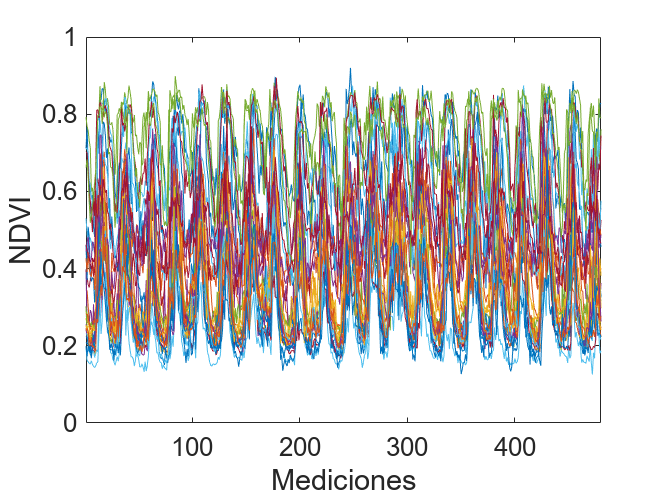

clear;
load tseries_test.mat;


figure;
plot(tseries_test');
xlabel('Mediciones')
ylabel('NDVI');
ylim([0 1]);
xlim([1 480]);
ax = gca;
ax.FontSize=16; 



[numero_series,tam_serie] = size(tseries_test);
stat_f = zeros(30,30);
stat_h = zeros(30,30);


for id=1:30
    S = tseries_test(id,:);

    for nh=1:6
        [Sh,Snan] = artificial_holes(S,nh);
        Sh = f_fill_mean_julian(Snan,23);
         

%         if any(id == [1 6 24])
%             figure;
%             plot(S);
%             hold on
%             plot(Snan,"b",LineWidth=2);
%             plot(Sh,"r");
%             hold off
%             legend('Original','Con huecos artificiales','Promedio de años otros años',Location='south');
%             xlabel('Mediciones')
%             ylabel('NDVI');
%             ylim([0 1]);
%             xlim([1 120]);
%             exportgraphics(gca,"img/Sh_Huecos_120_"+id+"_"+nh+".png",'Resolution',300); 
%         end

        Sf = ffilter_mean(Sh,0,23);
        [a,b,c,d,e] = compare_serie_stat(S,Sf);
        pos = (nh*5)-4;
        stat_f(id,pos) = a;
        stat_f(id,pos+1) = b;
        stat_f(id,pos+2) = c;
        stat_f(id,pos+3) = d;
        stat_f(id,pos+4) = e;
        
        [a,b,c,d,e] = compare_serie_stat(S,Sh);
        pos = (nh*5)-4;
        stat_h(id,pos) = a;
        stat_h(id,pos+1) = b;
        stat_h(id,pos+2) = c;
        stat_h(id,pos+3) = d;
        stat_h(id,pos+4) = e;

        
     
    end

end

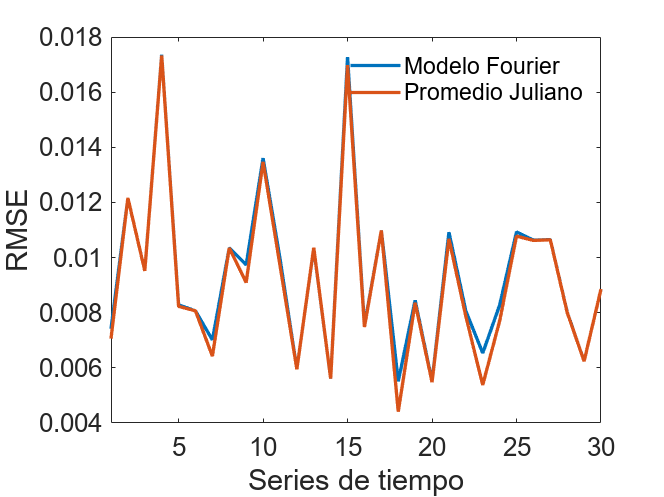

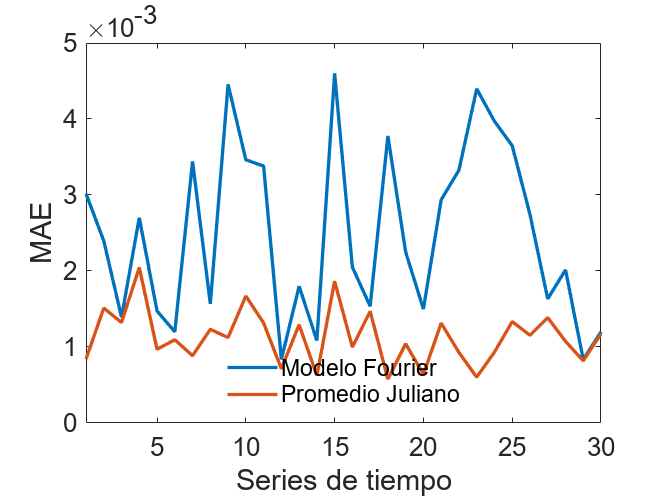

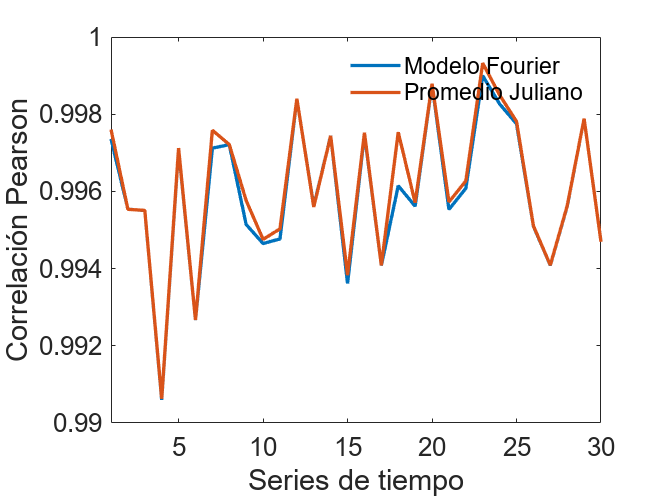

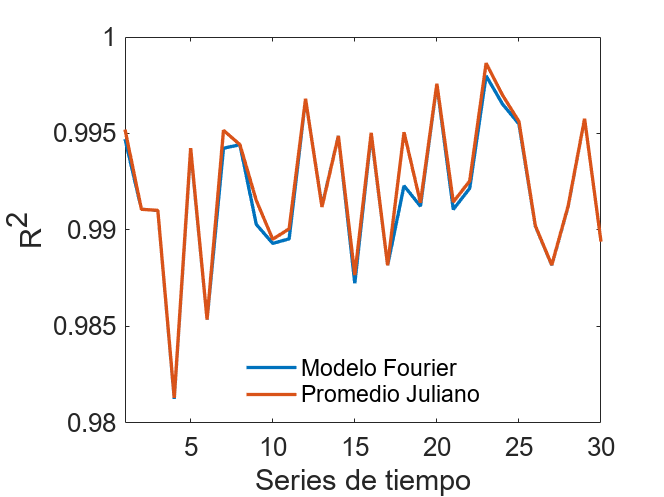

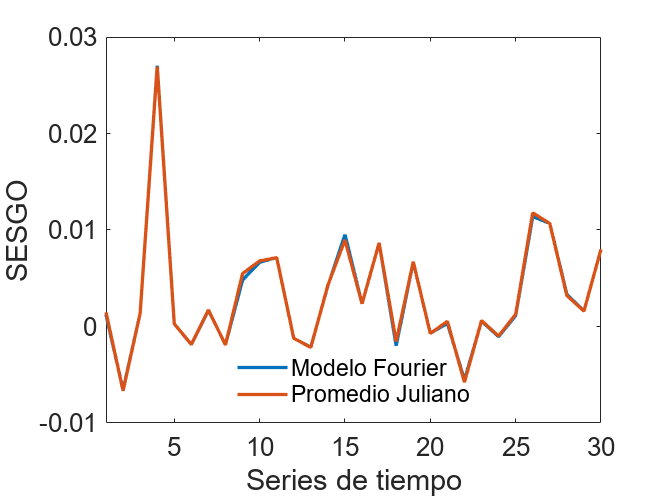

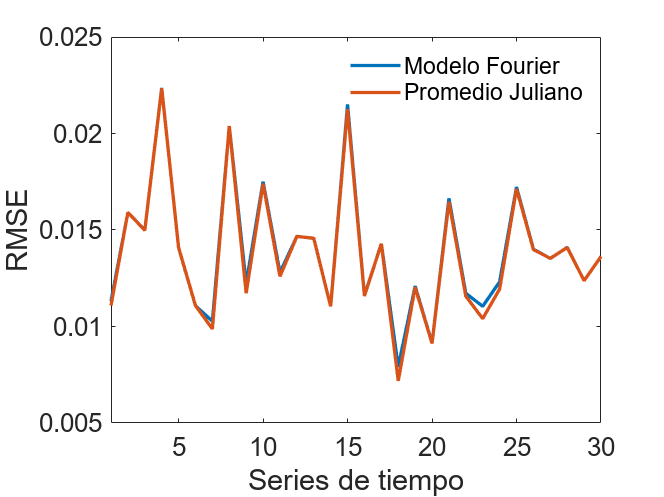

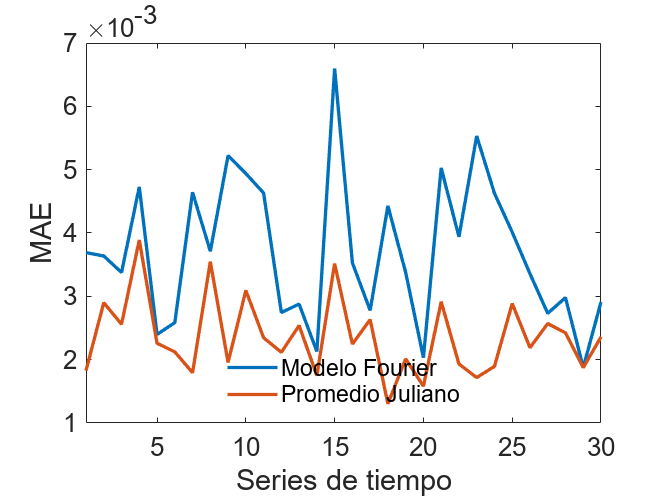

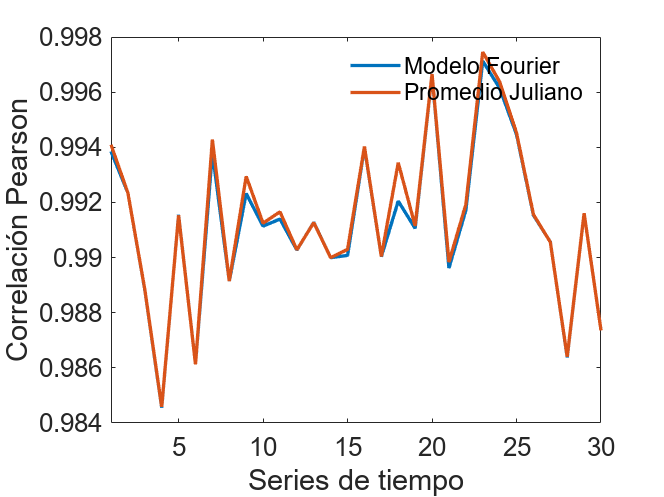

nh=1;
for nh=1:6
    pos = (nh*5)-4;
    %RMSE
    figure;
    plot(1:30,stat_f(:,pos),1:30,stat_h(:,pos),LineWidth=2);
    xlabel('Series de tiempo')
    ylabel('RMSE')
    xlim([1 30])
    %ylim([0 0.06]);
    ax = gca;
    ax.FontSize=16; 
    legend('Modelo Fourier','Promedio Juliano',Location='northeast');
    legend('boxoff');
%    exportgraphics(gca,"img/Sh_RMSE_TSF_H"+nh+".png",'Resolution',300) 
    
    %MAE
    figure;
    plot(1:30,stat_f(:,pos+1),1:30,stat_h(:,pos+1),LineWidth=2);
    xlabel('Series de tiempo')
    ylabel('MAE')
    xlim([1 30])
    %ylim([0.7 1]);
    ax = gca;
    ax.FontSize=16; 
    legend('Modelo Fourier','Promedio Juliano',Location='south');
    legend('boxoff');
%    exportgraphics(gca,"img/Sh_R2_TSF_H"+nh+".png",'Resolution',300) 

     %CORR
    figure;
    plot(1:30,stat_f(:,pos+2),1:30,stat_h(:,pos+2),LineWidth=2);
    xlabel('Series de tiempo')
    ylabel('Correlación Pearson')
    xlim([1 30])
    %ylim([0 0.06]);
    ax = gca;
    ax.FontSize=16; 
    legend('Modelo Fourier','Promedio Juliano',Location='northeast');
    legend('boxoff');
%    exportgraphics(gca,"img/Sh_RMSE_TSF_H"+nh+".png",'Resolution',300) 
    
    %MAE
    figure;
    plot(1:30,stat_f(:,pos+3),1:30,stat_h(:,pos+3),LineWidth=2);
    xlabel('Series de tiempo')
    ylabel('R^2')
    xlim([1 30])
    %ylim([0.7 1]);
    ax = gca;
    ax.FontSize=16; 
    legend('Modelo Fourier','Promedio Juliano',Location='south');
    legend('boxoff');
%    exportgraphics(gca,"img/Sh_R2_TSF_H"+nh+".png",'Resolution',300) 

     %SESGO
    figure;
    plot(1:30,stat_f(:,pos+4),1:30,stat_h(:,pos+4),LineWidth=2);
    xlabel('Series de tiempo')
    ylabel('SESGO')
    xlim([1 30])
    %ylim([0.7 1]);
    ax = gca;
    ax.FontSize=16; 
    legend('Modelo Fourier','Promedio Juliano',Location='south');
    legend('boxoff');
%    exportgraphics(gca,"img/Sh_R2_TSF_H"+nh+".png",'Resolution',300) 
end

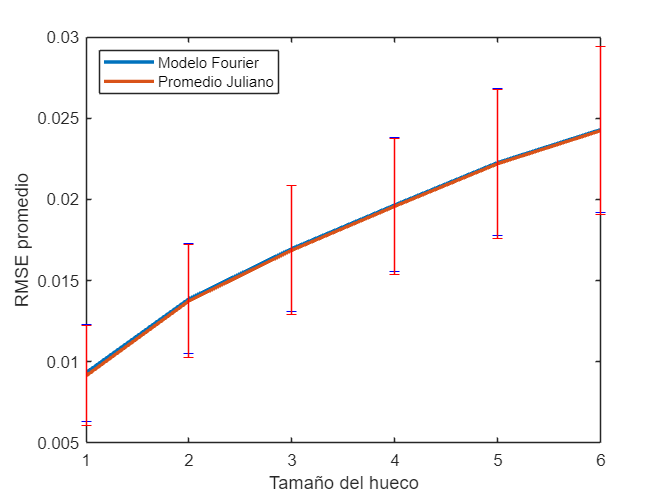

% Resumen
media_h =mean(stat_h);
media_f = mean(stat_f);

std_h =std(stat_h);
std_f = std(stat_f);


ids = 1:5:30;
%RMSE
figure;
p1=plot(1:6,media_f(ids),1:6,media_h(ids),LineWidth=2);
xlabel('Tamaño del hueco')
ylabel('RMSE promedio')
%xlim([1 30])
%ylim([0 0.05]);
hold on
er=errorbar(1:6,media_f(ids),std_f(ids)); 
er.Color = [0 0 1];                          
er.LineStyle = 'none';  
er=errorbar(1:6,media_h(ids),std_h(ids)); 
er.Color = [1 0 0];	                           
er.LineStyle = 'none'; 
% er=errorbar(1:6,media_s(1:2:12),std_s(1:2:12)); 
% er.Color = [1 1 0];	                           
% er.LineStyle = 'none'; 
hold off
%legend('Filtro fourier','Lanczos');
legend(p1,{'Modelo Fourier','Promedio Juliano'},Location="northwest")

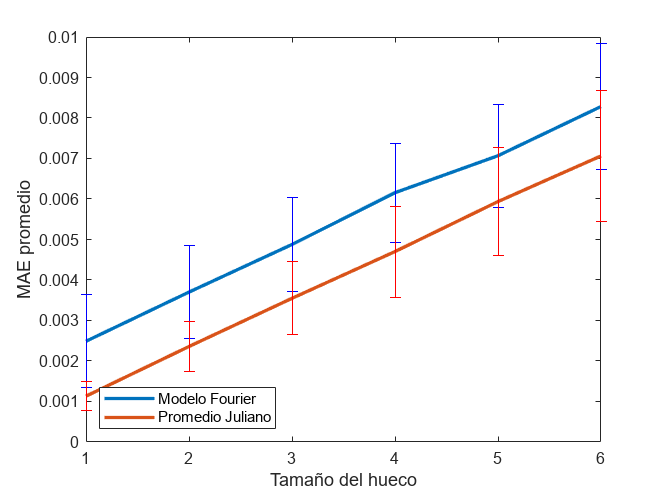

%exportgraphics(gca,"img/Sh_RMSE_TSF_mean.png",'Resolution',300) 


ids = 2:5:30;
%SESGO
figure;
p1=plot(1:6,media_f(ids),1:6,media_h(ids),LineWidth=2);
xlabel('Tamaño del hueco')
ylabel('MAE promedio')
%xlim([1 30])
%ylim([0.9 1]);
hold on
er=errorbar(1:6,media_f(ids),std_f(ids)); 
er.Color = [0 0 1];                          
er.LineStyle = 'none';  
er=errorbar(1:6,media_h(ids),std_h(ids)); 
er.Color = [1 0 0];	                           
er.LineStyle = 'none'; 
% er=errorbar(1:6,media_s(2:2:12),std_s(2:2:12)); 
% er.Color = [1 1 0];	                           
% er.LineStyle = 'none'; 
hold off
legend(p1,{'Modelo Fourier','Promedio Juliano'},Location="southwest")

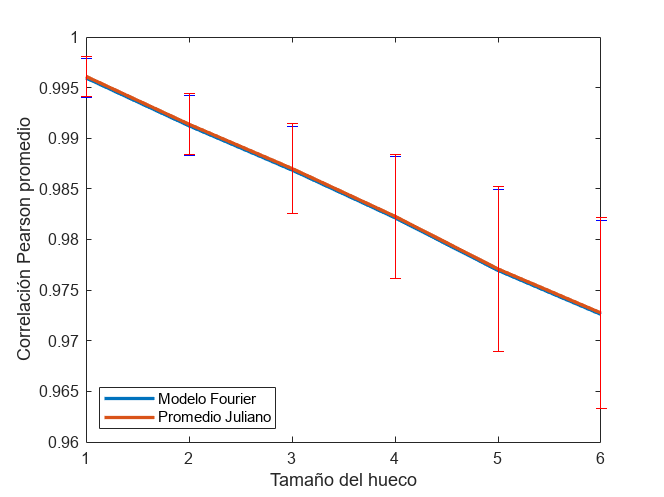

%exportgraphics(gca,"img/Sh_R2_TSF_mean.png",'Resolution',300) 

ids = 3:5:30;
%SESGO
figure;
p1=plot(1:6,media_f(ids),1:6,media_h(ids),LineWidth=2);
xlabel('Tamaño del hueco')
ylabel('Correlación Pearson promedio')
%xlim([1 30])
%ylim([0.9 1]);
hold on
er=errorbar(1:6,media_f(ids),std_f(ids)); 
er.Color = [0 0 1];                          
er.LineStyle = 'none';  
er=errorbar(1:6,media_h(ids),std_h(ids)); 
er.Color = [1 0 0];	                           
er.LineStyle = 'none'; 
% er=errorbar(1:6,media_s(2:2:12),std_s(2:2:12)); 
% er.Color = [1 1 0];	                           
% er.LineStyle = 'none'; 
hold off
legend(p1,{'Modelo Fourier','Promedio Juliano'},Location="southwest")

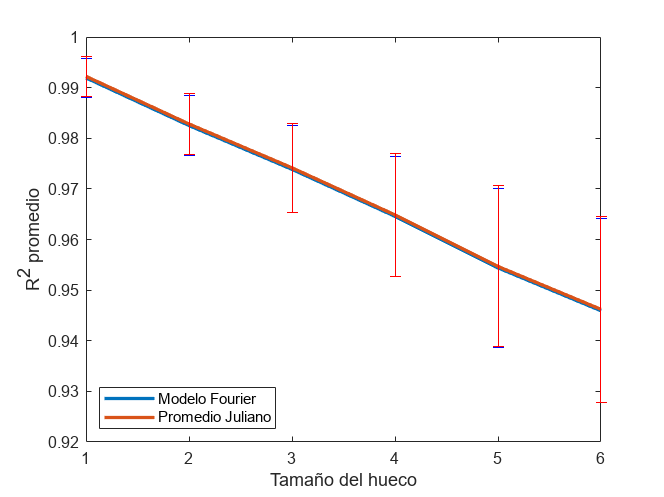

%exportgraphics(gca,"img/Sh_R2_TSF_mean.png",'Resolution',300) 

ids = 4:5:30;
%SESGO
figure;
p1=plot(1:6,media_f(ids),1:6,media_h(ids),LineWidth=2);
xlabel('Tamaño del hueco')
ylabel('R^2 promedio')
%xlim([1 30])
%ylim([0.9 1]);
hold on
er=errorbar(1:6,media_f(ids),std_f(ids)); 
er.Color = [0 0 1];                          
er.LineStyle = 'none';  
er=errorbar(1:6,media_h(ids),std_h(ids)); 
er.Color = [1 0 0];	                           
er.LineStyle = 'none'; 
% er=errorbar(1:6,media_s(2:2:12),std_s(2:2:12)); 
% er.Color = [1 1 0];	                           
% er.LineStyle = 'none'; 
hold off
legend(p1,{'Modelo Fourier','Promedio Juliano'},Location="southwest")

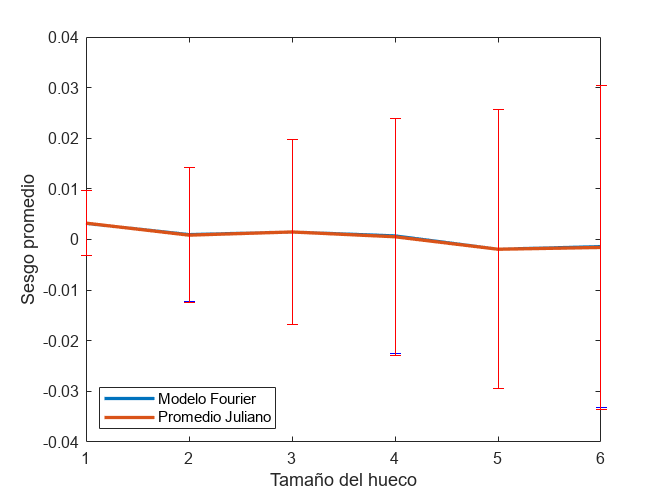

%exportgraphics(gca,"img/Sh_R2_TSF_mean.png",'Resolution',300) 


ids = 5:5:30;
%SESGO
figure;
p1=plot(1:6,media_f(ids),1:6,media_h(ids),LineWidth=2);
xlabel('Tamaño del hueco')
ylabel('Sesgo promedio')
%xlim([1 30])
%ylim([0.9 1]);
hold on
er=errorbar(1:6,media_f(ids),std_f(ids)); 
er.Color = [0 0 1];                          
er.LineStyle = 'none';  
er=errorbar(1:6,media_h(ids),std_h(ids)); 
er.Color = [1 0 0];	                           
er.LineStyle = 'none'; 
% er=errorbar(1:6,media_s(2:2:12),std_s(2:2:12)); 
% er.Color = [1 1 0];	                           
% er.LineStyle = 'none'; 
hold off
legend(p1,{'Modelo Fourier','Promedio Juliano'},Location="southwest")

%exportgraphics(gca,"img/Sh_R2_TSF_mean.png",'Resolution',300) 


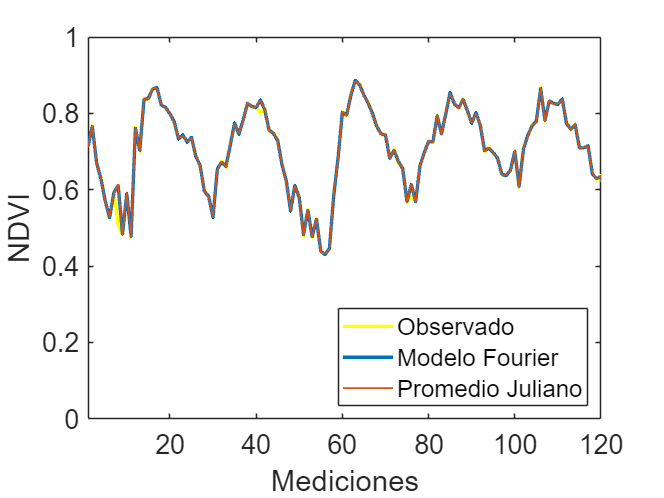

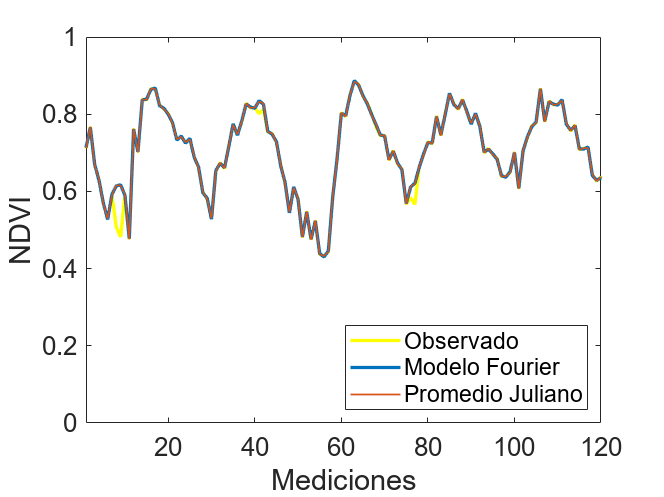

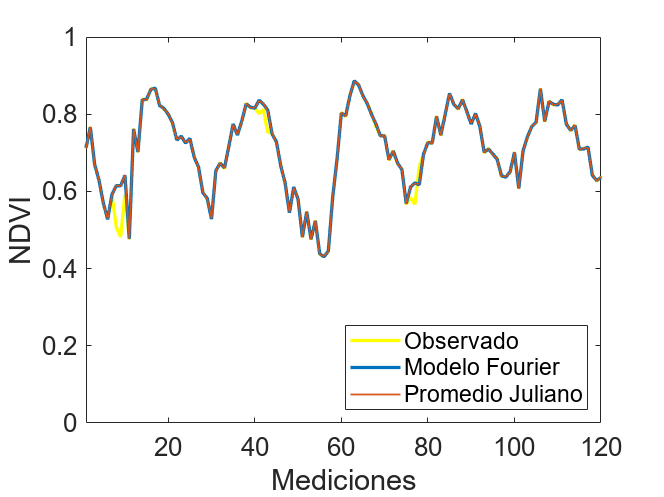

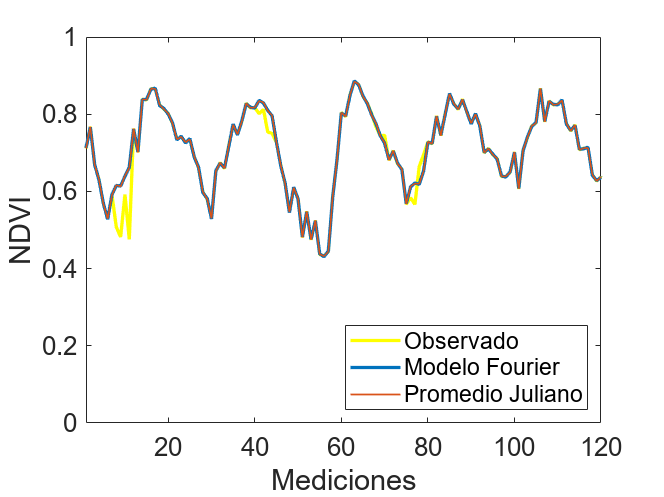

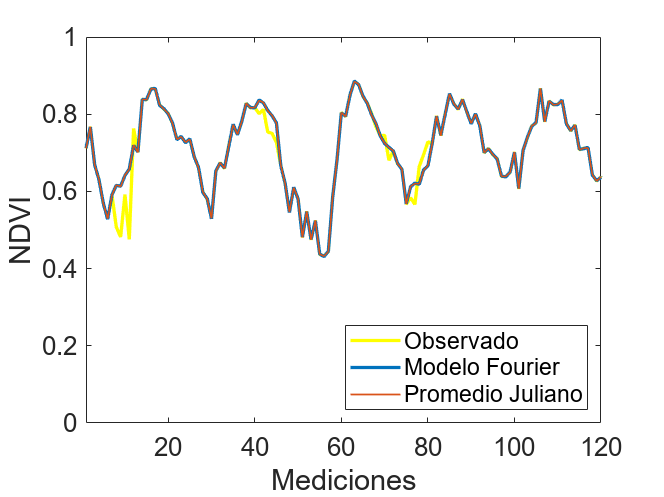

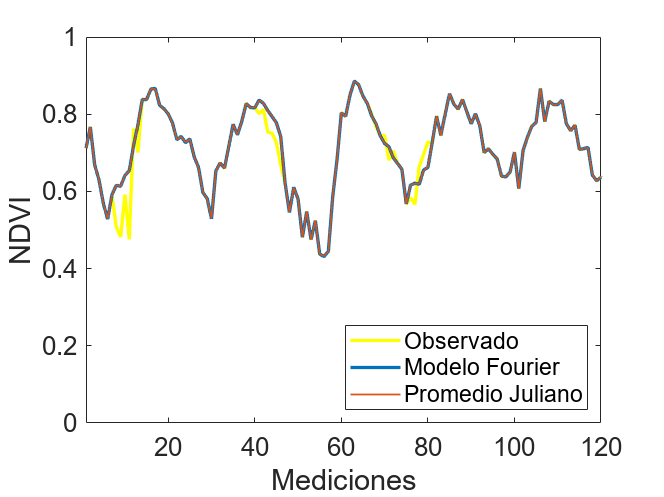

id=1;
    S = tseries_test(id,:);

    for nh=1:6
        [Sh,Snan] = artificial_holes(S,nh);
        Sh = f_fill_mean_julian(Snan,23);
        Sf = ffilter_mean(Sh,0,23);

        figure;
        plot(S,"y",LineWidth=2);
        hold on
        % plot(Sl,"r");
        plot(Sf, LineWidth=2,Color="#0072BD");
        plot(1:tam_serie,Sh, LineWidth=1,Color="#D95319");%,1:tam_serie,Snan);
        hold off
        legend('Observado','Modelo Fourier','Promedio Juliano',Location='southeast');
        xlabel('Mediciones')
        ylabel('NDVI');
        ylim([0 1]);
        xlim([1 120]);
        ax = gca;
        ax.FontSize=16; 
        %figure;
        % yyaxis left;
        % plot(1:30,stat_f(:,1));
        % xlabel('Rng')
        % ylabel('RMSE')
        % xlim([1 30])
        % 
        % yyaxis right;
        % plot(1:30,stat_f(:,2));
        % ylabel('R2')
        %exportgraphics(gca,"img/Sh_completar"+nh+".png",'Resolution',300) 

    end 

function [Sh,Snan] = artificial_holes(S,tam_huecos)
    id_huecos= [7 40 66 75 120 197 263 291 341 401 438];
    Snan=S;
    for i=id_huecos
        for j=1:tam_huecos
            Snan(i+j)=nan;
        end
    end
     Sh = Snan;
%     for i=id_huecos
%         for j=1:tam_huecos
%             idp = (i+j):23: length(S);
%             prom = mean(Sh(idp),"all","omitnan");
%             Sh(i+j) = prom;
%         end
%     end
end

% % function [Smean] = fill_mean_julian(Snan)
% %     tam = length(Snan);
% %     Smean = Snan;
% %     for i=1:tam
% %         if(isnan(Snan(i)))
% %             idp = i:23:tam;
% %             prom = mean(Snan(idp),"all","omitnan");
% %             Smean(i) = prom;
% %         end
% %     end
% % end


function [Sf,Yf,f,P1] = ffilter_mean(Sh,rng,Fs)
    L = length(Sh);      % Length of signal
    mit = L/2;

    Yf = fft(Sh);
    Yf(mit-rng+1:mit+rng+1) = 0;

    Yfp = abs(Yf);
    P2 = abs(Yfp/L);
    P1 = P2(1:int16(L/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
    Sf = real(ifft(Yf));
end

function [m_rmse,m_mae,m_corr,m_r2,m_sesgo] = compare_serie_stat(S,Sl)
    m_rmse = f_rmse(S,Sl);
    m_mae = f_mae(S,Sl);
    cor = corrcoef(S,Sl);
    m_corr = cor(2,1);
    mdl = fitlm(S,Sl);
    %m_R2o = mdl.Rsquared.Ordinary;
    m_r2 = mdl.Rsquared.Adjusted;
    m_sesgo = f_skewness(Sl,S);
end